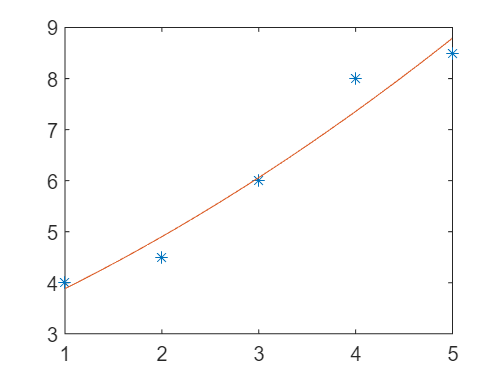

clc,clear,close all
x = [1,2,3,4,5];        % 已知点x坐标
y = [4,4.5,6,8,8.5];    % 已知点y坐标
omega = [2 1 3 1 1];    % 权重
xx = linspace(x(1),x(end),100);
syms t
varphi = [1,t,t^2];
[yy,S] = least_squares(x,y,omega,varphi,xx);
plot(x,y,'*')
hold on
plot(xx,yy)

disp(S)

$$0.06944\,x^{2}+0.8102\,x+3.005$$

delta = (y - least_squares(x,y,omega,varphi,x))

$$delta = \left(\begin{array}{ccccc} 0.11574074074360396480187773704529 & -0.40277777777373557910323143005371 & -0.060185185179761901963502168655396 & 0.64351851852552499622106552124023 & -0.29166666665787488454952836036682 \end{array}\right)$$

disp('均方误差')

均方误差


disp(sqrt(sum(delta.^2)))

$$0.13568672839519029276960767240508$$

disp('最大误差')

最大误差


disp(max(abs(delta)))

$$0.64351851852552499622106552124023$$